# Extract eYFP background

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

## Part 0: Initialization

Specify the dataset to analyze

% We need to specify the prefix of the project we wish to analyze
Prefix = '2020-10-07-vasa-eYFP_background';

Initialize some parameters

minAP = 0.1;
maxAP = 0.6;

maxT = 40;


## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/' Prefix];

mkdir(FigPath)
% Specify the position of DynamicsResults folder
DynamicsResultsFolder = '/Users/jiaxi.zhao/Dropbox/OptoDropbox';

Now, load all the data

% Now we'll load the CompiledParticles dataset
LoadNucleiPath = [DynamicsResultsFolder '/' Prefix '/' Prefix '_lin.mat'];
LoadComNucleiPath = [DynamicsResultsFolder '/' Prefix '/CompiledNuclei.mat']; 
data.nuclei = load(LoadComNucleiPath);
load(LoadNucleiPath)

ElapsedTime = data.nuclei.ElapsedTime;
start_frame = data.nuclei.nc14;
final_frame = length(ElapsedTime);

ElapsedTime = data.nuclei.ElapsedTime-data.nuclei.ElapsedTime(start_frame);
Time = ElapsedTime(start_frame:final_frame);
APbinID = data.nuclei.APbinID;

## Draw figures for nuclei

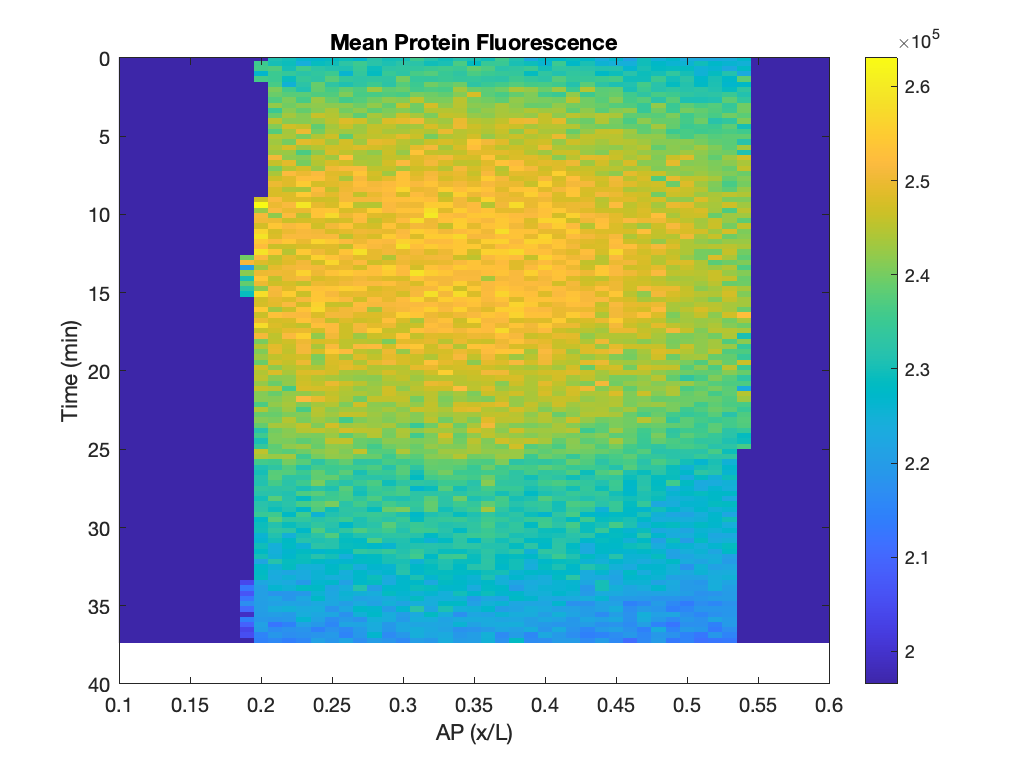

data_plot = data.nuclei.MeanVectorAP(start_frame:final_frame,:);
%data_plot = data.nuclei.MeanVectorAP(start_frame:final_frame,:)/correction_factor;
% Embryo 7/10
%data_plot(1:switch_frame-1) = data_plot(1:switch_frame-1)/correction_factor_1;
%data_plot(switch_frame:end) = data_plot(switch_frame:end)/correction_factor_2;

MeanNucleiFig = figure;
imagesc(APbinID,Time,data_plot);
xlabel('AP (x/L)')
ylabel('Time (min)')
xlim([minAP maxAP])
ylim([0 40])
colorbar
%caxis([0 12E5])
title('Mean Protein Fluorescence')
saveas(MeanNucleiFig,[FigPath '/MeanProtein_fluo.pdf' ]);

## Plot average concentration for all AP bins

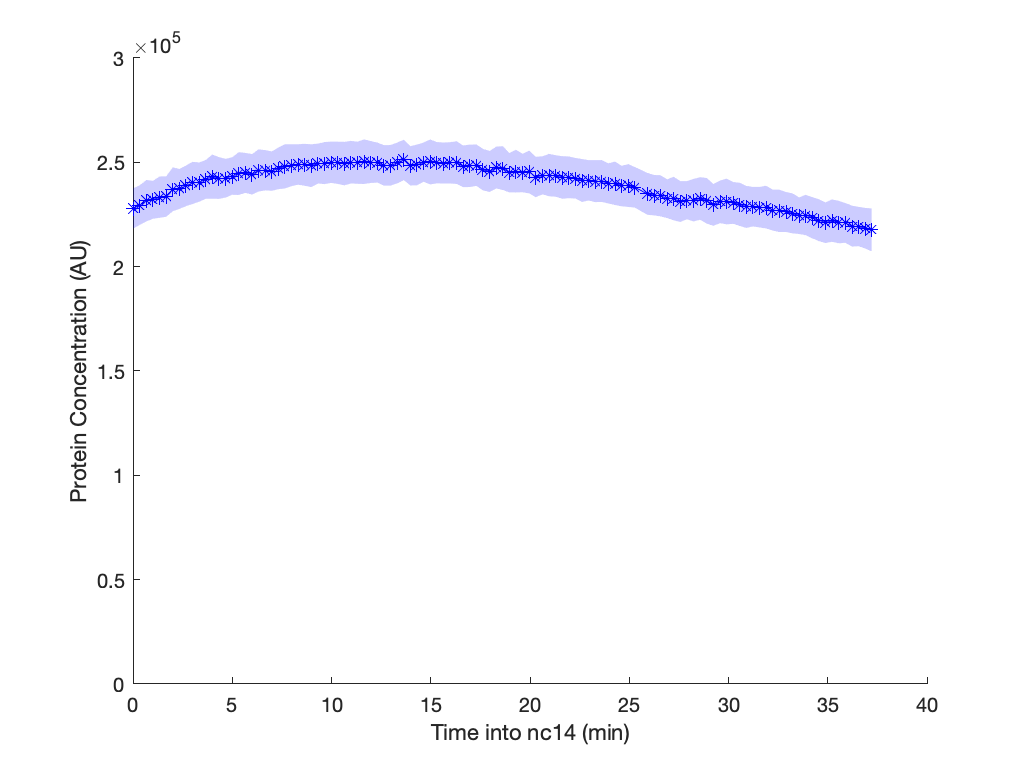

protein = data.nuclei.MeanVectorAll;
error = data.nuclei.SDVectorAll;

OverlayFig = figure;
xlabel('Time into nc14 (min)')
boundedline(Time,protein(start_frame:final_frame),error(start_frame:final_frame), '-b*','nan', 'gap','alpha');
ylabel('Protein Concentration (AU)')
ylim([0 3E5])

mean(protein(start_frame:final_frame))

ans = single
2.3911e+05